# ENOB over Temperature

测试目的：利用热风枪改变芯片温度，利用热敏电阻反应温度变化，在变温的同时，不停地进行Calibration & A/D Conversion，从而绘制ENOB over Temperature的曲线；

clear
clc

## 搭建通信通道

- visa - GPIB for DS360;

- visa - UART for FPGA;

% visadevlist
% visa_gpib = visadev("GPIB0::8::INSTR")
serialportlist

ans = "COM4"

baudrate = 256000;
visa_uart = serialport("COM4",baudrate)

visa_uart =   Serialport - 属性:

                 Port: "COM4"
             BaudRate: 256000
    NumBytesAvailable: 0

  Show all properties, functions


pause(1)
% UART Command
CB = 203;    % Calibration: 8'hCB = 8'd203;
AD = 173;    % A/D Conversion: 8'hAD = 8'd107;


## Calibration Process

N_Calibration = 1000;

if (visa_uart.NumBytesAvailable > 0)
    read(visa_uart,visa_uart.NumBytesAvailable,'uint8')
end
write(visa_uart, CB, 'uint8');

data_uart_in_cb = read(visa_uart,4*N_Calibration,'uint8');

if (visa_uart.NumBytesAvailable == 0)
    disp("Data reading from Serial Port Ready!")
else
    disp("Reading error!");
end

Data reading from Serial Port Ready!



data_N4_calib = data_bin2array(data_uart_in_cb)

data_N4_calib =     -1    15     3   -12
     1   -16     9     0
    -1    15     2     3
     1   -16     9    -1
    -1    15     2     4
     1   -16     9     1
    -1    15     2     4
     1   -16     9     2
    -1    15     2     4
     1   -16     9    12


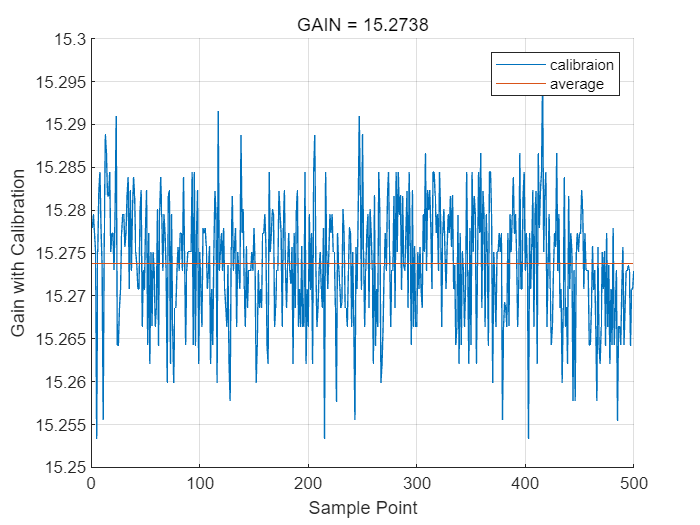

[Gain_list, GAIN] = deltaGain(data_N4_calib(:,2:end), 10, 'on');

## A/D Conversion (Low Speed)

N_Sample = 102400;
Vref = 1.8;
N_SUB = 5;
LSB_SUB = 1.8 / 2^N_SUB;
if (visa_uart.NumBytesAvailable > 0)
    read(visa_uart,4*visa_uart.NumBytesAvailable,'uint8')
end

write(visa_uart, AD, 'uint8');

data_uart_in_ad = read(visa_uart,4*N_Sample,'uint8');

if (visa_uart.NumBytesAvailable == 0)
    disp("Data reading from Serial Port Ready!")
end

Data reading from Serial Port Ready!


data_N4_ad = data_bin2array(data_uart_in_ad)

data_N4_ad =    -20     2     0    -6
   -19   -10     5    -9
   -19    -6     0     4
   -19    -2    -3    -7
   -19     2    -6    -4
   -19     5     7    -5
   -19     9     5     2
   -18    -2    -1     2
   -18     2    -1    -1
   -18     6    -1     7


fclock = 50E6 / 1;              
fs = fclock / 25                % sample rate = 2 MHz;

fs = 2000000

fin = 3/1280*fs                  % fin = 5/64*fs;

fin = 4.6875e+03

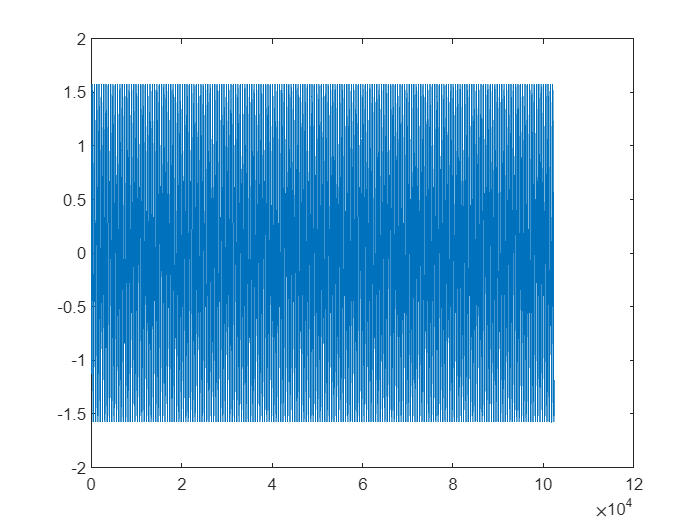


Vout_N4 = data_N4_ad * LSB_SUB;
% ~~~~~~~~~~~~~~~ Flash ~~~~~~~~~~~~~~~
figure
plot(Vout_N4(1:end,1));

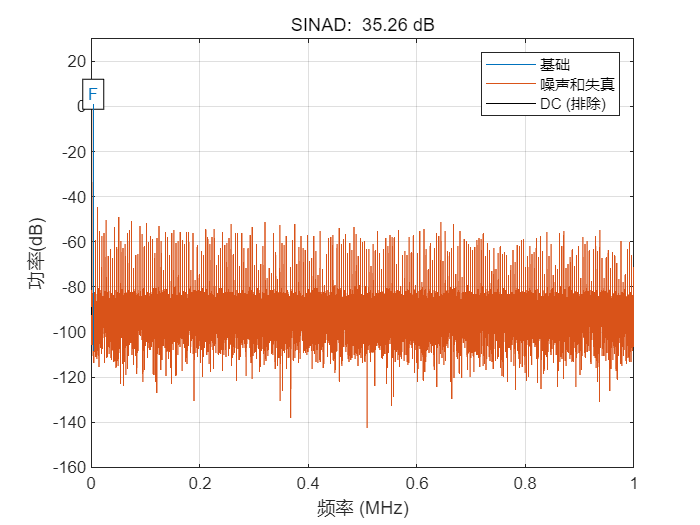

sinad(Vout_N4(:,1), fs);

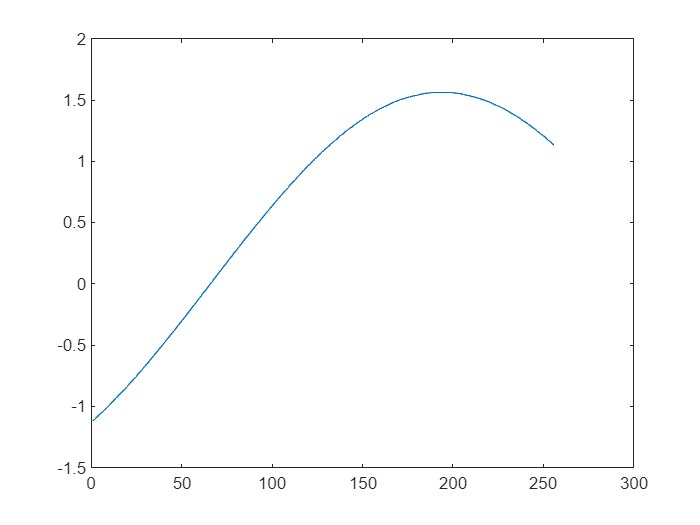


% ~~~~~~~~~~~~~~~ without calibration ~~~~~~~~~~~~~~~
Vout_without_calib = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_without_calib(i) = Calib_Gain(Vout_N4(i,:), 16);
end
plot(Vout_without_calib(1:256,1));

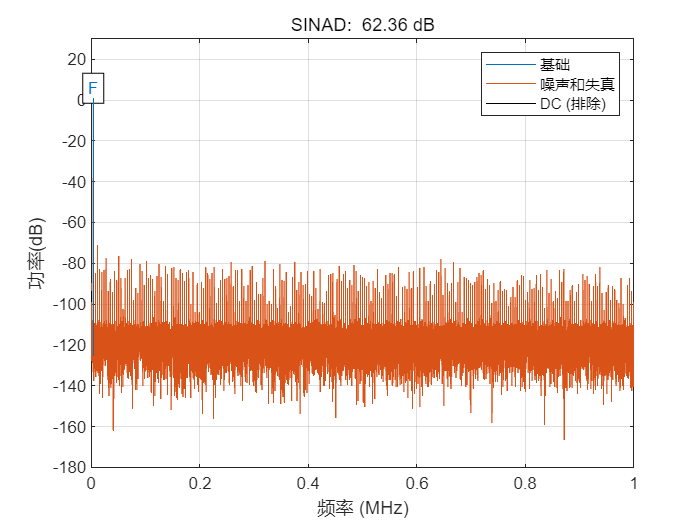

ans = 62.3574

sinad(Vout_without_calib, fs)

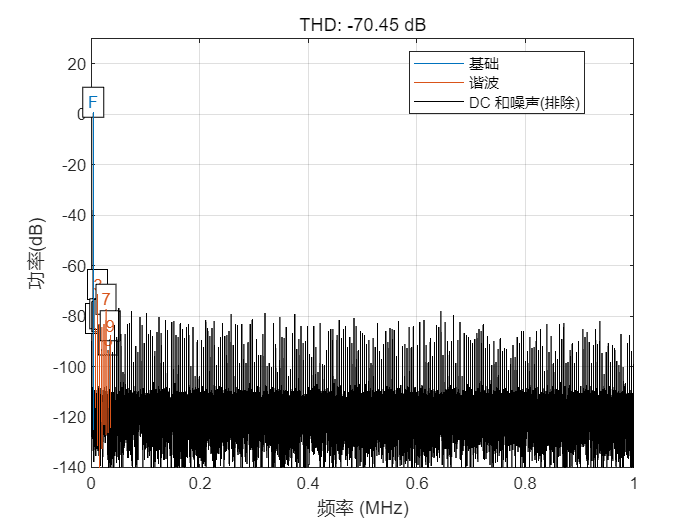

ans = -70.4497

thd(Vout_without_calib, fs, 9, 'aliased')

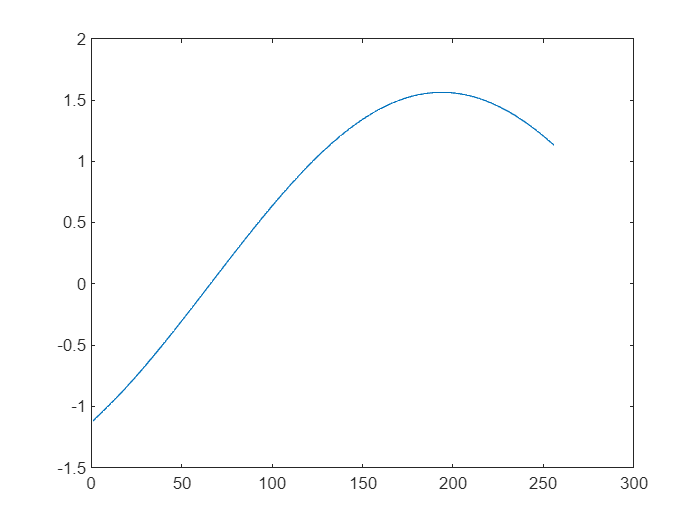

% ~~~~~~~~~~~~~~~ with calibration ~~~~~~~~~~~~~~~
Vout_mean_calib = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_mean_calib(i) = Calib_Gain(Vout_N4(i,:), GAIN);
%     Vout_mean_calib(i) = Calib_Gain(Vout_N4(i,:), 15.4);
end
plot(Vout_mean_calib(1:256,1));

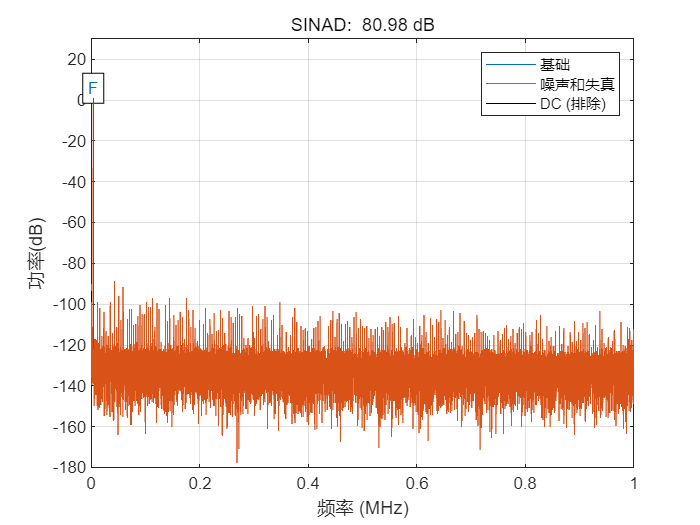

ans = 80.9793

sinad(Vout_mean_calib, fs)

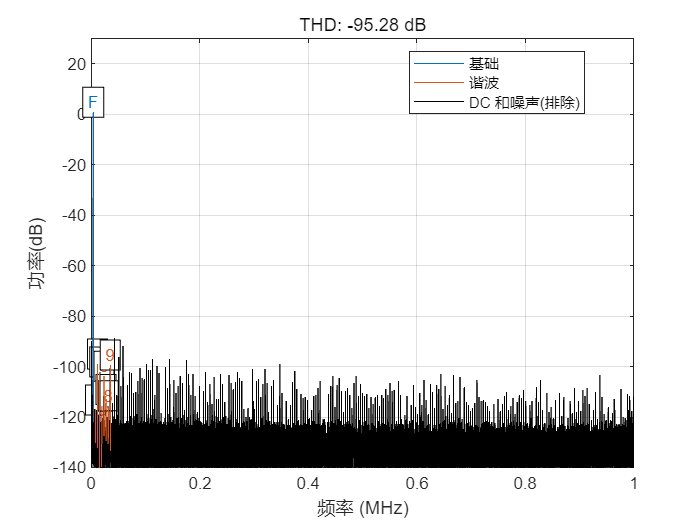

ans = -95.2821

thd(Vout_mean_calib , fs, 9, 'aliased')

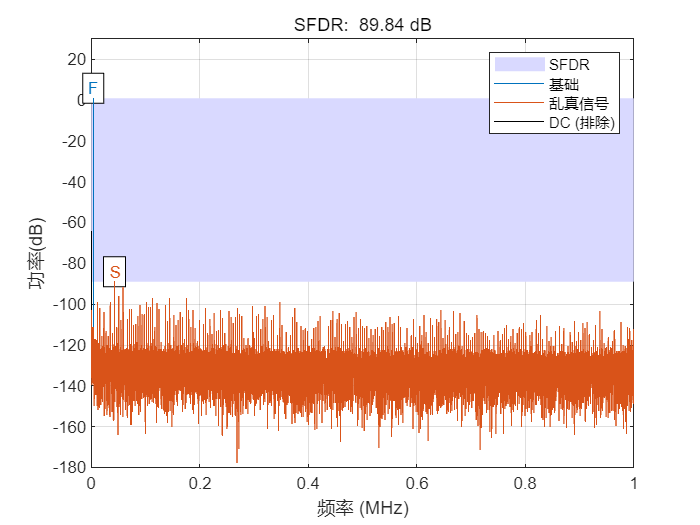

ans = 89.8408

sfdr(Vout_mean_calib, fs)

max(Vout_mean_calib)

ans = 1.5624

20*log10(Vref / max(Vout_mean_calib))

ans = 1.2297

## Noise Analysis

write(visa_uart, AD, 'uint8');
if (visa_uart.NumBytesAvailable > 0)
    read(visa_uart,4*visa_uart.NumBytesAvailable,'uint8')
end
data_uart_in_noise = read(visa_uart,4*N_Sample,'uint8');

if (visa_uart.NumBytesAvailable == 0)
    disp("Data reading from Serial Port Ready!")
end

Data reading from Serial Port Ready!


data_N4_noise = data_bin2array(data_uart_in_noise);
Vout_N4_Noise = data_N4_noise * LSB_SUB;

Vout_noise = zeros(N_Sample, 1);
for i=1:N_Sample
    Vout_noise(i) = Calib_Gain(Vout_N4_Noise(i,:), GAIN);
%     Vout_mean_calib(i) = Calib_Gain(Vout_N4(i,:), 15.4);
end

Noise_RMS = pow2db(var(Vout_noise))

Noise_RMS = -88.8275

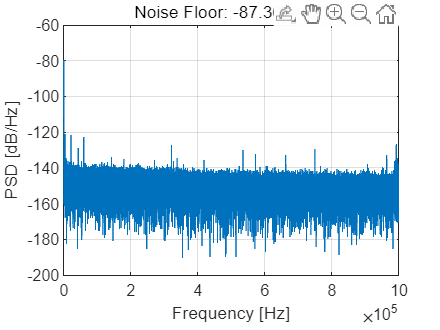


[pxx, f] = periodogram(Vout_noise, ...
        rectwin(N_Sample), N_Sample, fs, 'PSD');
figure
plot(f, 10*log10(pxx));
xlabel('Frequency [Hz]');
ylabel('PSD [dB/Hz]')
grid on
title(['Noise Floor: ', num2str(Noise_RMS), ' dB'])